# Using Extreme Value Theory and Copulas to Evaluate Market Risk

This example shows how to model the market risk of a hypothetical global equity index portfolio with a Monte Carlo simulation technique using a Student's t copula and Extreme Value Theory (EVT). 

**Key Steps: **

1) Model variance of the residuals with an asymmetric GARCH model

2) Construct a marginal cumulative distribution function (CDF) of each asset using a Gaussian kernel estimate for the interior and a generalized Pareto distribution (GPD) estimate for the upper and lower tails.

3) Fit a Student's t copula to the data and used to induce correlation between the simulated residuals of each asset.

4) Assess the Value-at-Risk (VaR) of the hypothetical global equity portfolio over a one month horizon.

Note that this is a relatively advanced, comprehensive example that assumes some familiarity with EVT and copulas. 

## Import Global Equity Indices & Setup Key Variables

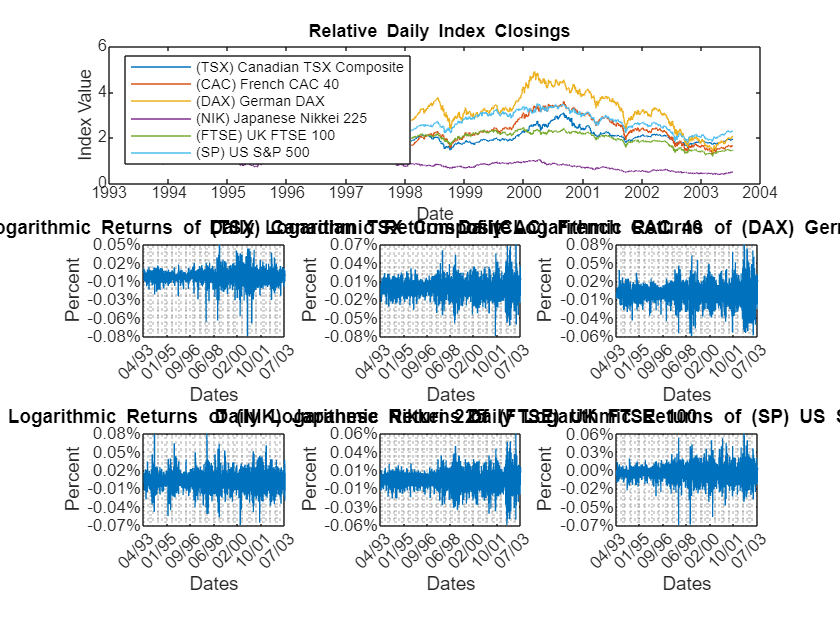

load GlobalEquityIndices   % Daily index closings
Returns = price2ret(Data);    % Logarithmic returns - continuosly compounded returns
Plot_NormalizedPriceSeries(Dates,Data,Returns,Names)

## Filter the Returns for Each Index

Modeling the tails of a distribution with a GPD requires the observations to be approximately independent and identically distributed (i.i.d.). However, most financial return series exhibit some degree of autocorrelation and, more importantly, heteroskedasticity.

For example, the sample autocorrelation function (ACF) of the returns associated with the selected index reveal some mild serial correlation.

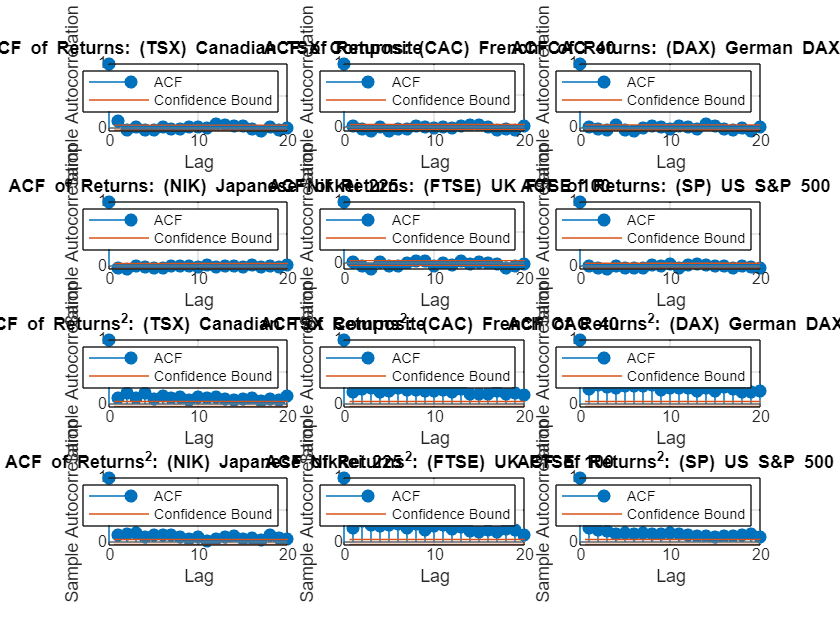

Plot_AutoCorrOfReturns(Returns,Names)

## Fit an AutoRegressive Model with GARCH Effects using GJR

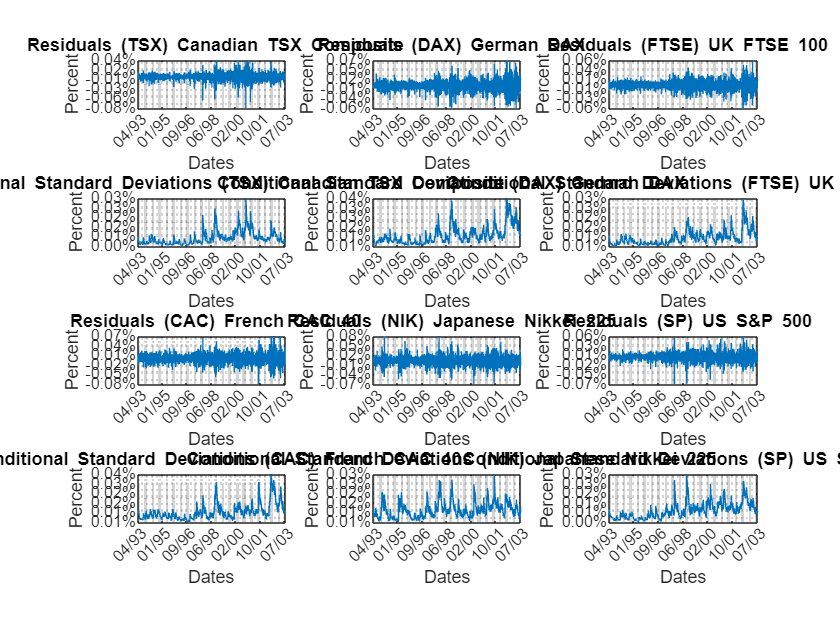

LoadSavedModel = true; % Loading model for demonstration ONLY due to long model fit times
if LoadSavedModel
    Data = load('AR_GJR_GarchModel.mat');
    ModelFit     = Data.ModelFit;
    ei_Residuals = Data.Residuals;
    Variances    = Data.Variances;
else
    [ModelFit,ei_Residuals,Variances] = Build_AR_GJRModel(Returns);
end
Plot_ResidualsAndVariances(Dates,ei_Residuals,Variances,Names)

## Visualize Residuals & Variances

ei_ResidualsNormalized = ei_Residuals ./ sqrt(Variances);
Plot_AutoCorrOfReturns(Returns,Names)

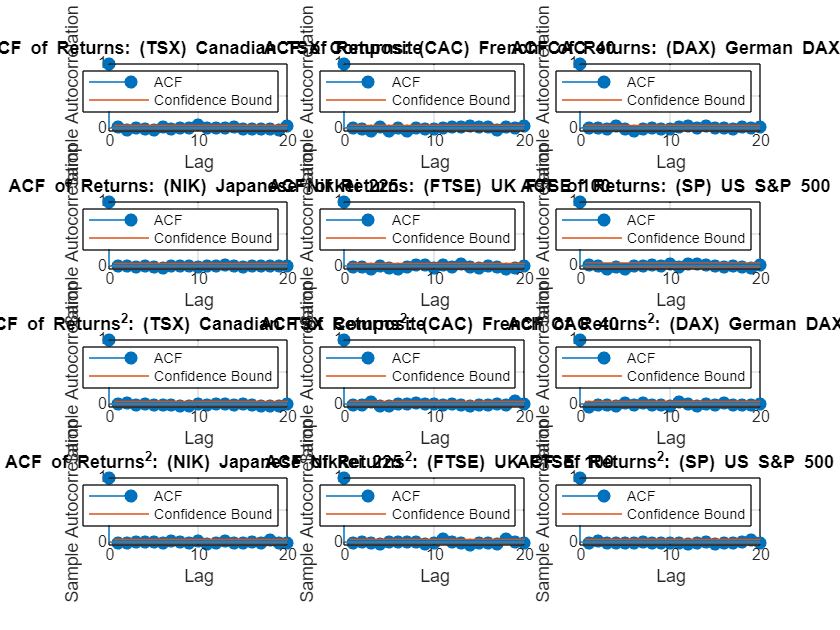

Plot_AutoCorrOfReturns(ei_ResidualsNormalized,Names)

## Estimate the Semi-Parametric CDFs using a Pareto for the Tails

nPoints      = 200;      % # of sampled points of kernel-smoothed CDF
tailFraction = 0.1;      % Decimal fraction of residuals allocated to each tail
nIndices     = size(Returns,2);
DistributionObject = cell(nIndices,1);  % Cell array of Pareto tail objects

for i = 1:nIndices
    DistributionObject{i} = paretotails(ei_Residuals(:,i), tailFraction, 1 - tailFraction, 'kernel');
end

## Evaluate the GPD Fit

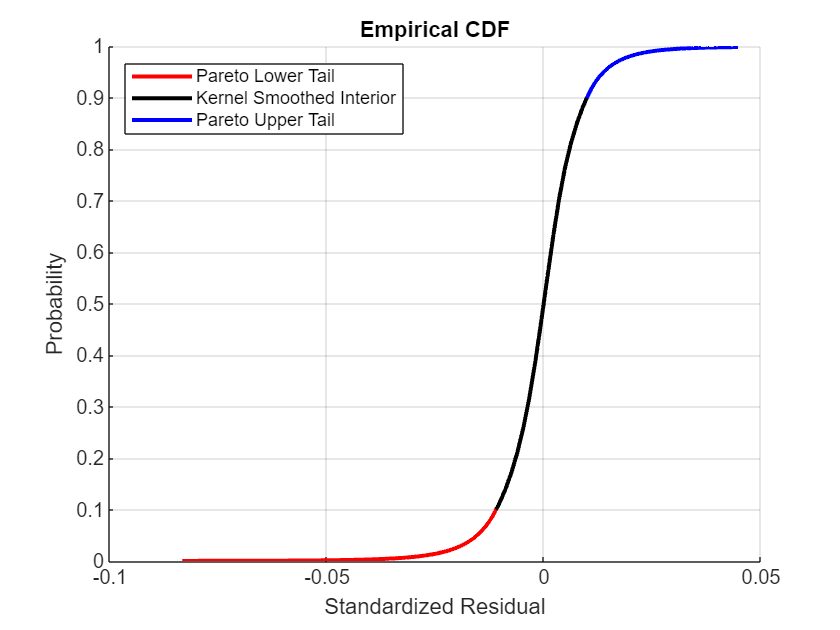

Plot_ParetoTailObject(DistributionObject,ei_Residuals,Names,'Semiparametric')

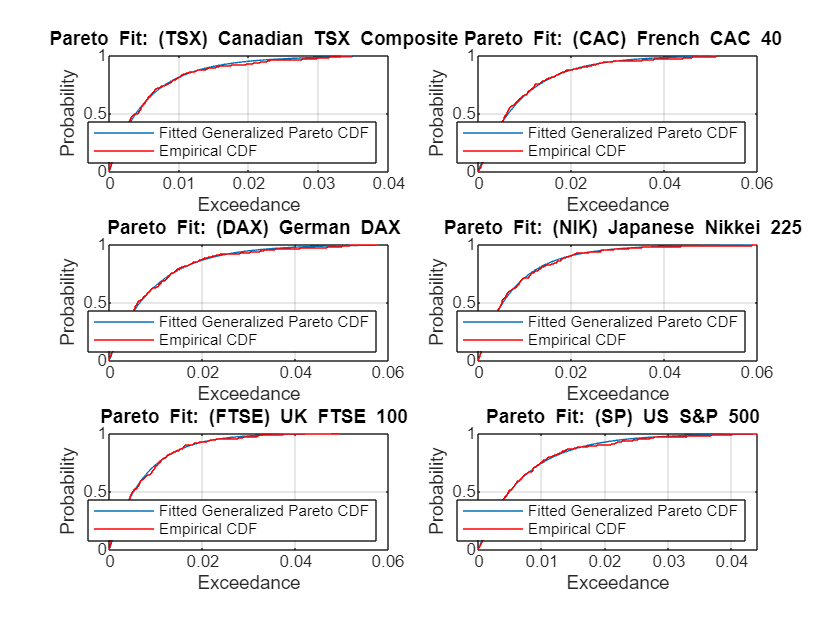

Plot_ParetoTailObject(DistributionObject,ei_Residuals,Names,'All')

## Calibrate the t Copula

Given the standardized residuals, now estimate the scalar degrees of freedom parameter (DoF) and the linear correlation matrix (R) of the t copula using the `copulafit` function found in the Statistics Toolbox. The `copulafit` function allows users to estimate the parameters of the t copula by two distinct methods.

The default method is a formal maximum likelihood approach performed in a two-step process.

Specifically, although the full log-likelihood could be maximized directly, the maximum of the objective function often occurs in a long, flat, narrow valley in multi-dimensional space, and convergence difficulties may arise in high dimensions. To circumvent these difficulties, `copulafit` performs the maximum likelihood estimation (MLE) in two steps. The inner step maximizes the log-likelihood with respect to the linear correlation matrix, given a fixed value for the degrees of freedom. That conditional maximization is placed within a 1-D maximization with respect to the degrees of freedom, thus maximizing the log-likelihood over all parameters. The function being maximized in this outer step is known as the profile log-likelihood for the degrees of freedom.

In contrast, the following code segment uses an alternative which approximates the profile log-likelihood for the degrees of freedom parameter for large sample sizes. Although this method is often significantly faster than MLE, it should be used with caution because the estimates and confidence limits may not be accurate for small or moderate sample sizes. 

Specifically, the approximation is derived by differentiating the log-likelihood function with respect to the linear correlation matrix, assuming the degrees of freedom is a fixed constant. The resulting non-linear equation is then solved iteratively for the correlation matrix. This iteration is, in turn, nested within another optimization to estimate the degrees of freedom. This method is similar in spirit to the profile log-likelihood method above, but is not a true MLE in that the correlation matrix does not converge to the conditional MLE for a given degrees of freedom. However, for large sample sizes the estimates are often quite close to the MLE (see Bouye et al [1], and Durrleman, Nikeghbali, Roncalli [7]).

Yet another method estimates the linear correlation matrix by first computing the sample rank correlation matrix (Kendall's tau or Spearman's rho), then converts the rank correlation to a linear correlation with a robust sine transformation. Given this estimate of the linear correlation matrix, the log-likelihood function is then maximized with respect to the degrees of freedom parameter alone. This method also seems motivated by the profile log-likelihood approach, but is not an MLE method at all. However, this method does not require matrix inversion and therefore has the advantage of being numerically stable in the presence of close-to-singular correlation matrices (see Zeevi and Mashal [8]).

Finally, Nystrom and Skoglund [6] propose reserving the degrees of freedom parameter as a user-specified simulation input, thus allowing the user to subjectively induce the extent of tail dependence between assets. In particular, they recommend a relatively low degrees of freedom, somewhere between 1 and 2, thus allowing a closer examination of the likelihood of joint extremes. This method is useful for stress testing in which the degree of extreme codependence is of critical importance.

The code segment below first transforms the standardized residuals to uniform variates by the semi-parametric empirical CDF derived above, then fits the t copula to the transformed data. When the uniform variates are transformed by the empirical CDF of each margin, the calibration method is often known as canonical maximum likelihood (CML).

U = zeros(size(ei_Residuals));

for i = 1:nIndices
    U(:,i) = DistributionObject{i}.cdf(ei_Residuals(:,i)); % transform margin to uniform
end

[R, DoF] = copulafit('t', U, 'Method', 'ApproximateML'); % fit the copula

## Simulate Global Index Portfolio Returns with a t Copula

Given the parameters of a t copula, now simulate jointly dependent equity index returns by first simulating the corresponding dependent standardized residuals.

To do so, first simulate dependent uniform variates using the `copularnd` function found in the Statistics Toolbox.

Then, by extrapolating into the GP tails and interpolating into the smoothed interior, transform the uniform variates to standardized residuals via the inversion of the semi-parametric marginal CDF of each index. This produces simulated standardized residuals consistent with those obtained from the AR(1) + GJR(1,1) filtering process above. These residuals are independent in time but dependent at any point in time. Each column of the simulated standardized residuals array represents an i.i.d. univariate stochastic process when viewed in isolation, whereas each row shares the rank correlation induced by the copula.

The following code segment simulates 2000 independent random trials of dependent standardized index residuals over a one month horizon of 22 trading days.

s = RandStream.getGlobalStream(); reset(s)

nTrials = 2000;                                   % # of independent random trials
horizon = 22;                                     % VaR forecast horizon

Z = zeros(horizon, nTrials, nIndices);            % standardized residuals array
U = copularnd('t', R, DoF, horizon * nTrials);    % t copula simulation

for j = 1:nIndices
    Z(:,:,j) = reshape(DistributionObject{j}.icdf(U(:,j)), horizon, nTrials);
end

% Simulate Returns
% Using the simulated standardized residuals as the i.i.d. input noise process, 
% reintroduce the autocorrelation and heteroskedasticity observed in the 
% original index returns via the Econometrics Toolbox(TM) |filter| function.
%
% Note that |filter| accepts user-specified standardized disturbances derived 
% from the copula and simulates multiple paths for a single index model at a 
% time, which means that all sample paths are simulated and stored for each 
% index in succession. 
%
% To make the most of current information, specify the necessary presample 
% model residuals, variances, and returns so that each simulated path evolves  
% from a common initial state.

Y0 = Returns(end,:);                    % presample returns
Z0 = ei_Residuals(end,:);               % presample standardized Residuals
V0 = Variances(end,:);                  % presample variances

simulatedReturns = zeros(horizon, nTrials, nIndices);

for i = 1:nIndices
    simulatedReturns(:,:,i) = filter(ModelFit{i}, Z(:,:,i), ...
                                    'Y0', Y0(i), 'Z0', Z0(i), 'V0', V0(i));
end

% Reshape Returns
% Now reshape the simulated returns array such that each page represents a 
% single trial of a multivariate return series, rather than multiple trials of
% a univariate return series.

simulatedReturns = permute(simulatedReturns, [1 3 2]);

## Calculate Cumulative Returns (Equally Weighted Portfolio)

Finally, given the simulated returns of each index, form an equally weighted global index portfolio composed of the individual indices (a global index of country indices). Since we are working with daily logarithmic returns, the cumulative returns over the risk horizon are simply the sums of the returns over each intervening period. Also note that the portfolio weights are held fixed throughout the risk horizon, and that the simulation ignores any transaction costs required to rebalance the portfolio (the daily rebalancing process is assumed to be self-financing).

Note that although the simulated returns are logarithmic (continuously compounded), the portfolio return series is constructed by first converting the individual logarithmic returns to arithmetic returns (price change divided by initial price), then weighting the individual arithmetic returns to obtain the arithmetic return of the portfolio, and finally converting back to portfolio logarithmic return. With daily data and a short VaR horizon, the repeated conversions make little difference, but for longer time periods the disparity may be significant.

cumulativeReturns = zeros(nTrials, 1);
weights           = repmat(1/nIndices, nIndices, 1); % equally weighted portfolio

for i = 1:nTrials
    cumulativeReturns(i) = sum(log(1 + (exp(simulatedReturns(:,:,i)) - 1) * weights));
end

## Summarize the Results

Having simulated the returns of each index and formed the global portfolio, report the maximum gain and loss, as well the VaR at various confidence levels, over the one month risk horizon. Also, plot the empirical CDF of the global portfolio.

Maximum Simulated Loss:  -0.5681%
Maximum Simulated Gain:   0.9366%

     Simulated 90% VaR:   0.6800%
     Simulated 95% VaR:   0.6655%
     Simulated 99% VaR:   0.6429%



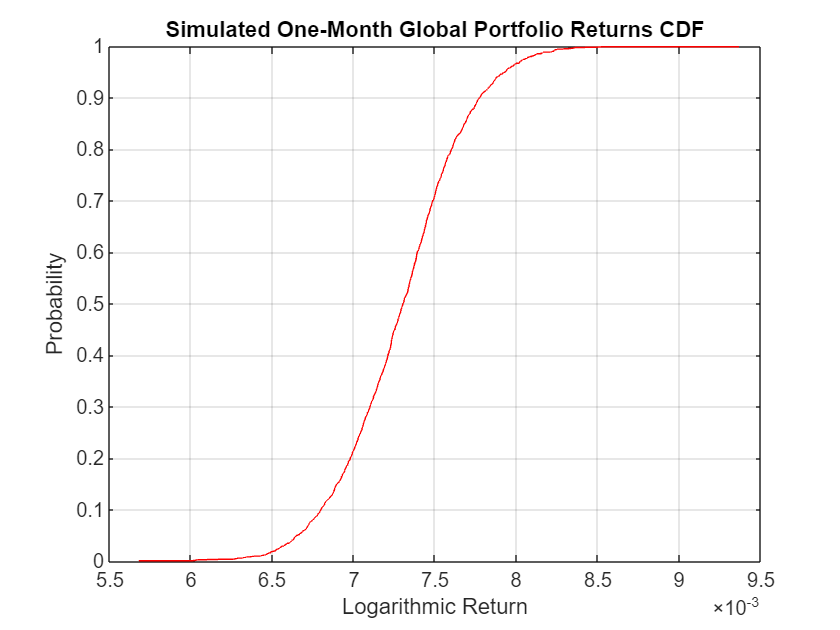

VaR = 100 * quantile(cumulativeReturns, [0.10 0.05 0.01]');
summarizeResults(cumulativeReturns,VaR)

fprintf('Maximum Simulated Loss: %8.4f%s\n'   , -100*min(cumulativeReturns), '%')

Maximum Simulated Loss:  -0.5681%


fprintf('Maximum Simulated Gain: %8.4f%s\n\n' ,  100*max(cumulativeReturns), '%')

Maximum Simulated Gain:   0.9366%



fprintf('     Simulated 90%% VaR: %8.4f%s\n'  ,  VaR(1), '%')

     Simulated 90% VaR:   0.6800%


fprintf('     Simulated 95%% VaR: %8.4f%s\n'  ,  VaR(2), '%')

     Simulated 95% VaR:   0.6655%


fprintf('     Simulated 99%% VaR: %8.4f%s\n\n',  VaR(3), '%')

     Simulated 99% VaR:   0.6429%




figure
h = cdfplot(cumulativeReturns);
set(h, 'Color', 'Red');
xlabel('Logarithmic Return')
ylabel('Probability')
title ('Simulated One-Month Global Portfolio Returns CDF')

## Bibliography

This example is based on the following papers and journal articles; many of these may be found at [http://www.gloriamundi.org](http://www.gloriamundi.org).

[1] Bouye, E., Durrleman, V., Nikeghbali, A., Riboulet, G., Roncalli, T. (2000), "Copulas for Finance: A Reading Guide and Some Applications".

[2] Embrechts, P., McNeil, A., Straumann, D. (1999), "Correlation and Dependence in Risk Management: Properties and Pitfalls".

[3] Glosten, L.R., Jagannathan, R., Runkle, D.E. (1993), "On the Relation between Expected Value and the Volatility of the Nominal Excess Return on Stocks", The Journal of Finance, vol. 48, pp. 1779-1801.

[4] McNeil, A. and Frey, R. (2000), "Estimation of Tail Related Risk Measure for Heteroscedastic Financial Time Series: An Extreme Value Approach". Journal of Empirical Finance 7, 271-300.

[5] Nystrom, K., Skoglund, J. (2002), "Univariate Extreme Value Theory, GARCH and Measures of Risk", Preprint, Swedbank.

[6] Nystrom, K., Skoglund, J. (2002), "A Framework for Scenario-Based Risk Management", Preprint, Swedbank.

[7] Roncalli, T., Durrleman, A., Nikeghbali, A., (2000), "Which Copula Is the Right One?"

[8] Zeevi, A., Mashal, R., (2002), "Beyond Correlation: Extreme Co-movements between Financial Assets", Preprint, Columbia University.

*Copyright 1999-2010 The MathWorks, Inc.*